# Linear Control Design 2 - Fall 2021 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E21) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**All exercises are equally weighted towards the overall assessment of the examination.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E21'

Exam = 'LCD2 E21'

Student_Name = 'Eduard Maximilian Fiedler'

Student_Name = 'Eduard Maximilian Fiedler'

Student_Number = 's210134'

Student_Number = 's210134'

## Output feedback control of a test mass accelerometer

A test mass accelerometer is a measuring system utilized to measured vertical accelerations in e.g. vehicles. The figure below shows a simplified schematic of such device.

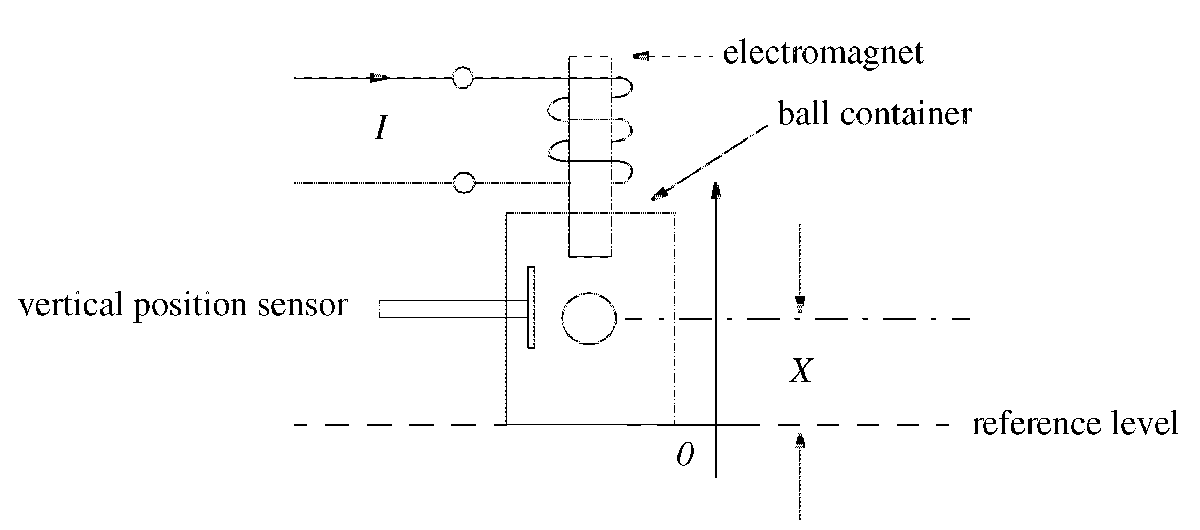

The test mass is a steel ball with a mass $m = 10\mathrm{g}$. The ball is held floating in a magnetic field by the electromagnet above it. The vertical position of the ball is measured by a position sensor.

The electromagnetic force that keeps the ball floating is given by


$$F_{em}(X,I) = 1.805\times10^3X^2 + 14.44XI - 6.498X + 0.02888I^2 + 0.374I - 0.1742$$


where $X$is the ball position (in meters) in relation to the reference point and $I$ is the current (in Amperes).

The ball is also influenced by the air resistance. The force that air resistance exerts on the ball is


$$F_{ar}(V) = -V(c_1 + c_2|V|)$$


where $c_1 = 1.55\times10^{-6}\mathrm{N}(m/s)$, $c_2 = 2.2\times 10^{-4}\mathrm{N(m/s)^2} $ and the ball's velocity $V$is expressed in $m/s$.

The accelerometer is under the influence of an external vertical acceleration $A$. The nonlinear model describing the motion of the ball reads


$$\frac{d^2X}{dt^2} = \frac{1}{m}F_{ar}(V)+\frac{1}{m}F_{em}(X,I) + A - g$$


where $g = 9.81\mathrm{m/s^2}$ is the acceleration of gravity.

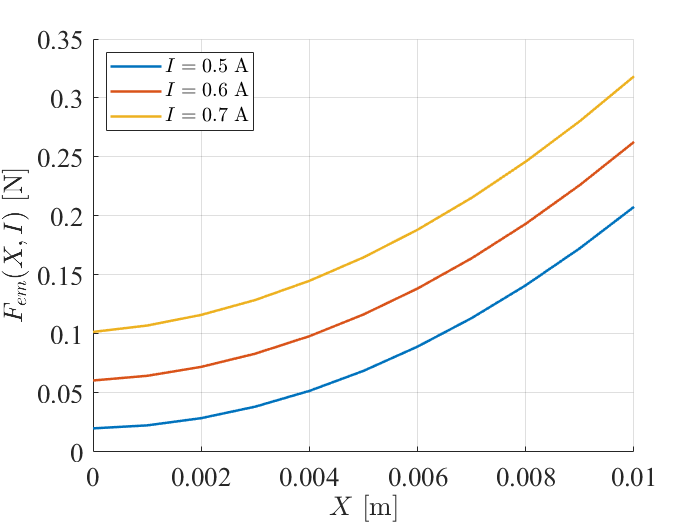

% Simulator parameters (RG)
SIM_TIME = 1; 
STEP_SIZE = 0.0001;
% Change with the name of the model you are using
SIMULINK_FILENAME = 'TestMassAccelerometer_NonlinearModel_Simulink2020b';

% Model paramters (RG)
m = 0.01; % mass in kilograms
c1 = 1.55*10^-6; % N*m/s
c2 = 2.2*10^-4; % N*m^2/s^2
% Coefficients of the electromagnetic force
f1 = 1.805*10^3; 
f2 = 14.44;
f3 = 6.498;
f4 = 0.02888;
f5 = 0.3740;
f6 = 0.1742;
% --------------------------------------------
g = 9.81; % m/s^2
A = 0; % m/s^2

% Electromagnetic force for different values of control current I (RG)
X = (0:0.001:0.01)'; % mass displacement range [m]
I0 = [0.5 0.6 0.7]; % control current [A]
for ii = 1:length(I0)
    F_em(:,ii) = f1*X.^2 + f2*X.*I0(ii) - f3*X + f4*I0(ii).^2 + f5*I0(ii) - f6;
end

figure, h1 = axes; set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(X,F_em,'LineWidth',1.5)
ylabel('$F_{em}(X,I)$ [N]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$X$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
leg = legend('$I = 0.5$ A','$I = 0.6$ A','$I = 0.7$ A','Location','NorthWest');
set(leg,'FontName','times','FontSize',12,'Interpreter','latex')

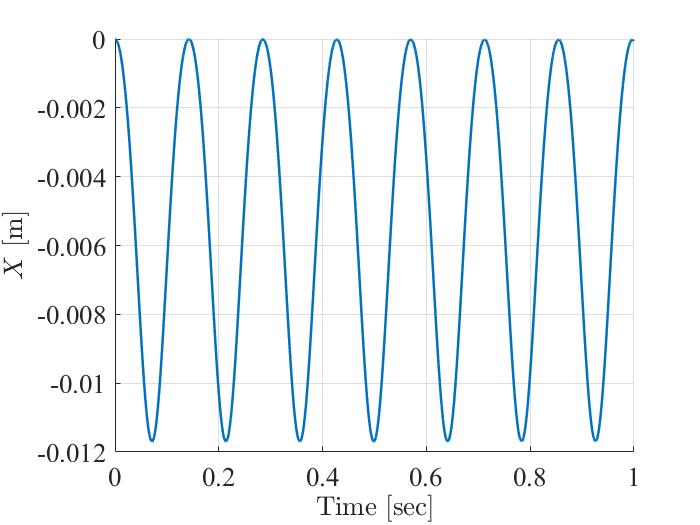

% Test the provided nonlinear model (RG)
time = (0:STEP_SIZE:SIM_TIME)';
x0 = zeros(2,1); % initial condition x0 = [X,V]'
I0 = 0.5; % test current through the electromagnet [A]
I = I0*ones(length(time),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time I])

% Plot simulation result
t = logsout.getElement(1).Values.Time;
X = logsout.getElement(1).Values.Data;
V = logsout.getElement(2).Values.Data;

figure, h2 = axes; set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(t,X,'LineWidth',1.5)
ylabel('$X$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

## Operating point and linearization

**Problem 1 (2 points) **Determine the operating point associated with a nominal verical displacement of the mass $X_n = 2.5\mathrm{mm}$ when the external vertical acceleration $A=0$. Linearize the system around the operatig point.

% Your solution goes here

A = 0;
% Estimate the initial state for V
x0 = [2.5e-3 0]';
% Estimate input to the system I
u0 = 0;
% Output of the system is equal to state 1
y0 = x0(1);

% When obtaining the stationary states, select to keep x0(1)
[xss,uss,yss] = trim('TestMassAccelerometer_NonlinearModel_Simulink2020b',x0,u0,y0,[1],[],[1]);

% Use the stationary states to linearise the system using linmod using the
% calculated stationary input and states.
[A,B,C,D] = linmod('TestMassAccelerometer_NonlinearModel_Simulink2020b',xss,uss)

A = 	1.0e+03 *

         0    0.0010
    1.1865   -0.0000


B =          0
   44.7450


C =      1     0


D = 0


% There is an external vertical acceleration, that acts like a disturbance
% to the second state V. Add this in the same manner as stated in the
% dynamic equation.
Bv = [0;1]

Bv =      0
     1



% g is said to be kept constant at 9.81m/s

## Stability analysis

**Problem 2 (2 points)** Assess the internal and external stability of the linear system.

% Your solution goes here

% The internal stability is based on the state matrix A, where the
% eigenvalues can be assessed.
eig(A)

ans =    34.4448
  -34.4450



% There is a positive real pole, therefore the system is internally
% unstable.

% The unstable pole may be cancelled in the external form of the system.
% Thus, the system can be transformed into its transfer function form,
% where the poles can be assessed.
[n_sys,d_sys] = ss2tf(A,B,C,D);
G_sys = minreal(tf(n_sys,d_sys))

G_sys =
 
           44.75
  ------------------------
  s^2 + 0.0001552 s - 1186
 
Continuous-time transfer function.



pole(G_sys)

ans =   -34.4450
   34.4448



% The transfer function of the system is still second order, and the poles
% are equal to the eigenvalues of A. Therefore, the instability remains,
% thus:

% The external system is BIBO unstable as one of its poles has a positive 
% real part.

## Control system design for measurement of external acceleration

The test mass accelerometer in opern loop is not capable of providing a measurement of the external vertical acceleration $A$. In order to enable the measuring device to provide such measurement a control system need to be designed.

Closed-loop system requirements

1) The position $X$ of the test mass is regulated to its nominal value $X_n$ despite step changes in the external vertical acceleration $A$.

2) For a step change in the external vertical acceleration $A$ equal to $0.25g$ at a time $t = t_{step}$ the position $X$ is regulated back to its nominal value $X_n$ with

        a) a maximum 20% deviation from its steady state value during the transient part of the response

        b) settling time between 50 and 75 milliseconds

Please refer to the following figure for a clear definition of the quantities described in the requirements. **IMPORTANT** The response shown in the figure (blue curve) serves only to display quantities of interest for the design requirements; therefore it does not necessarily represent the expected system behaviour.

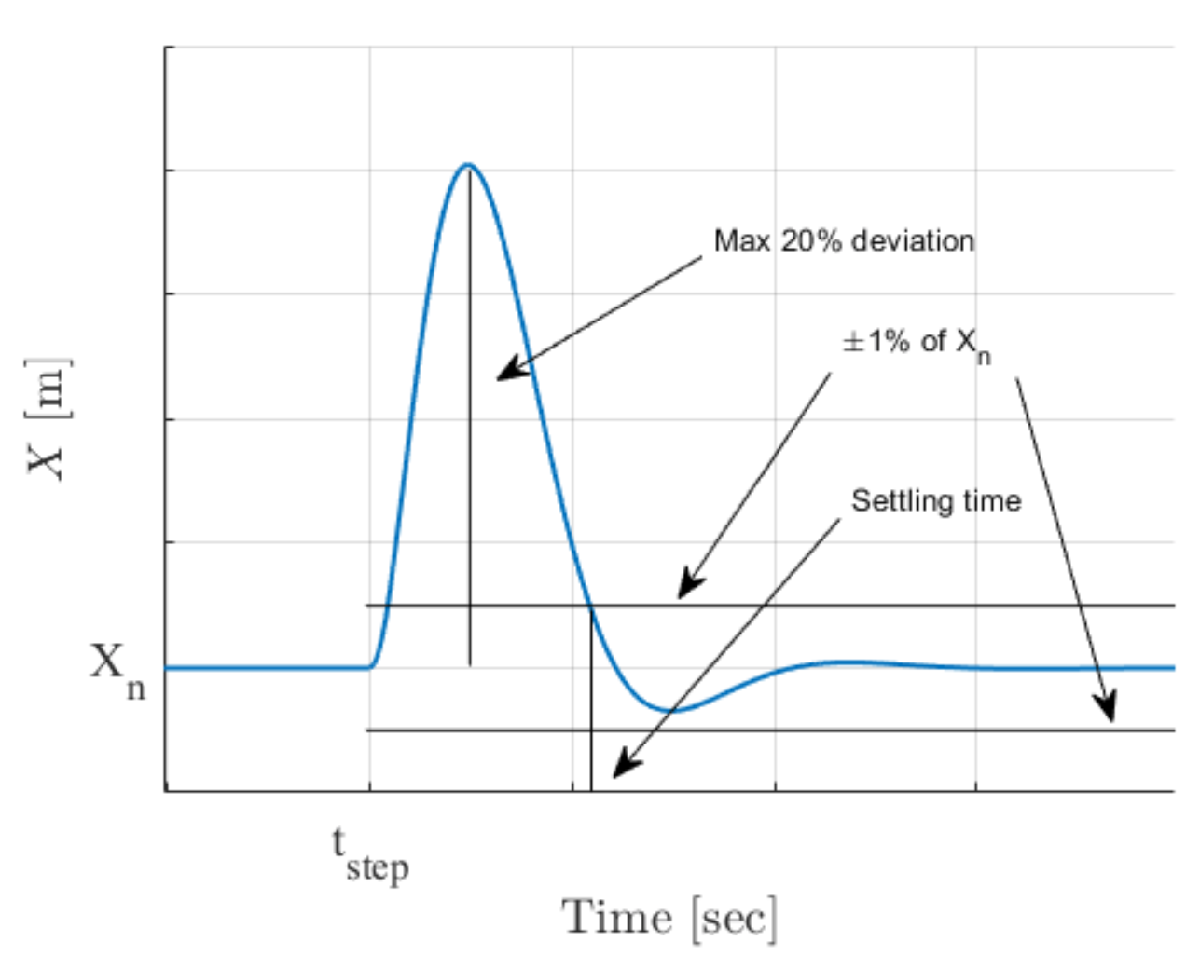

**Problem 3 (6 points)** Under the assumption that the state is fully accessible **design a discrete time optimal controller** that meets the aforementioned specifications on the nonlinear system.

% Your solution goes here

% Based on the conditions, the controlled system should do the following:
% 1. Bring the states back to the calculated stationary value -- must track
% reference to reject the disturbance caused by A
% 2. The external vertical acceleration should step by 0.25*g at a defined
% time t_step
A_0 = 0;
A_step = 0.25*g;
t_step = SIM_TIME/3;
% 3. Maximum deviation for state X is 20% from the steady-state value.
x_max = xss(1)+xss(1)*0.2;
% 4. The settling time, where state X is between +-1% of the steady-state
% value, should maximally be t_step + 75e-3
t_graph_set = t_step + 75e-3;
x_set_max = xss(1)*1.01;
x_set_min = xss(1)*0.99;
% 5. The control architecture used is a discrete-time LQR control.

% Identify the discrete-time system, such that the system can be augmented
% and the gains for the LQR control can be determined.

% Determine the sampling time
damp(A) % fastest time constant is 2.9e-2

                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
  3.44e+01    -1.00e+00       3.44e+01         -2.90e-02    
 -3.44e+01     1.00e+00       3.44e+01          2.90e-02    


t_set = 50e-3;

Ts = min([50e-3/10 2.9e-2/10]);
% Adjust such that the sampling time is compatible in the simulink system
Ts = Ts - rem(Ts,STEP_SIZE);

% Obtain discrete-time system
[F,G] = c2d(A,B,Ts);
[~,Gv] = c2d(A,Bv,Ts);

% Check if the system is controllable
rank(ctrb(F,G))-length(F) % Gives 0, therefore, the system is controllable.

ans = 0


% Augment the system to include the integral state. State matrix is 3x3
F_a = [F zeros(2,1);-Ts*C eye(1)];
G_a = [G;0]; % Input matrix is 3x1
C_a = [C 0]; % Output matrix is 1x3

% Set the weights for the controller
% High weighting for integral state is chosen, High weighting for tracking
% X, no condition for V given.
R1 = diag([0.1 0.01 1000000]);
% No condition on use of control effort lower means higher control effort
% may be used.
R2 = 0.01;

% Calculate the LQR gain
K = dlqr(F_a,G_a,R1,R2);
Kx = K(1:2); % Selects gains for the states
Ki = -K(3); % Selects gains for the integral state

% Check the stability of the closed-loop system
F_k = F_a - G_a*K;
l_dt = eig(F_k);

% Check if the settling time is achieved
l_ct = log(l_dt)/Ts

l_ct =  -41.8009 +58.0817i
 -41.8009 -58.0817i
 -87.3179 + 0.0000i


abs(real(l_ct(1)))<(5/75e-3)

ans = logical
   1


**Problem 4** **(2 points)** Implement the discrete time optimal controller in the Simulink model of the nonlinear system, and evalute the closed-loop system performance against the given requirements, when the sytem is subject to the step change in the external vertical acceleration $A$ of $0.25g$.

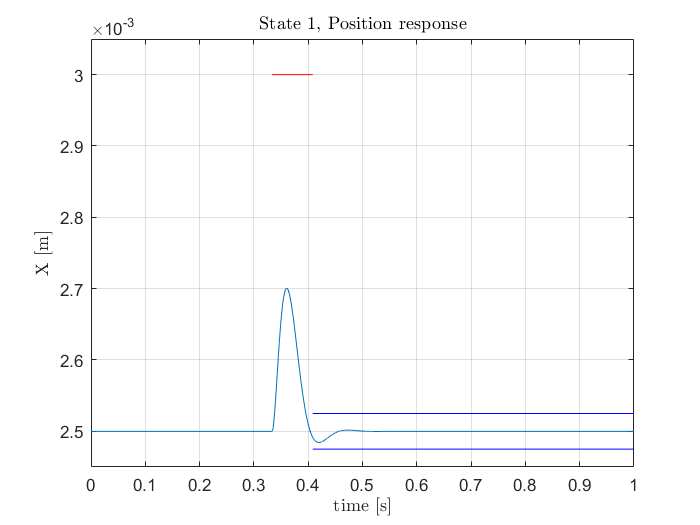

% Your solution goes here

% Implementing and remembering to offset values by their steady state, and
% initialising integrators at operating points.
sim('LQR_control')

figure
plot(simx.time,simx.signals.values(:,1))
line([t_step t_step+75e-3],[x_max x_max],'color','r')
line([t_step+75e-3 1],[x_set_max x_set_max],'color','b')
line([t_step+75e-3 1],[x_set_min x_set_min],'color','b')
ylim([2.45e-3 3.05e-3])
grid('on')
title('State 1, Position response','interpreter','latex')
ylabel('X [m]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

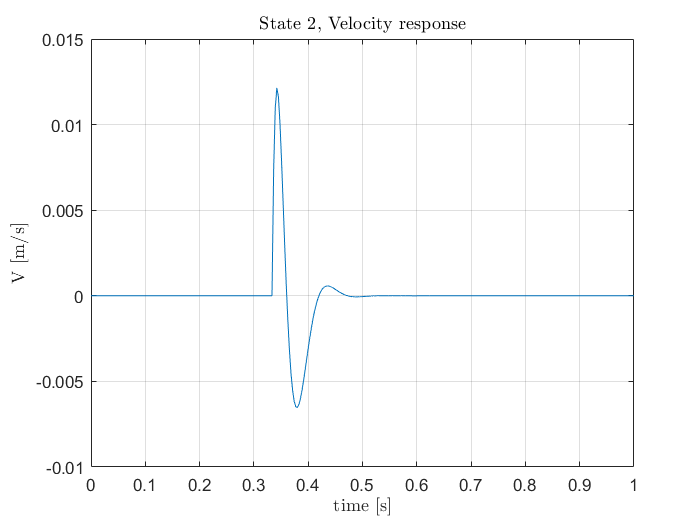


% The maximum deviation is avoided, as the maximum is below the red line
% The settling time is achieved, as the response is within the blue bars
% before t_graph_set

figure
plot(simx.time,simx.signals.values(:,2))
grid('on')
title('State 2, Velocity response','interpreter','latex')
ylabel('V [m/s]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

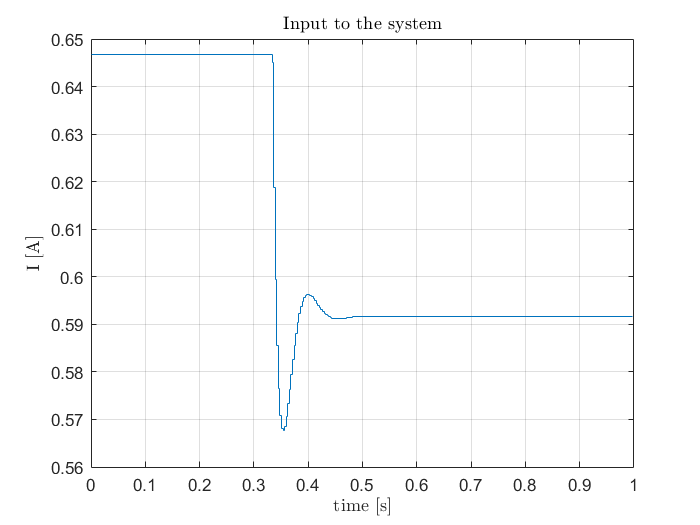


figure
stairs(simu.time,simu.signals.values(:,1))
grid('on')
title('Input to the system','interpreter','latex')
ylabel('I [A]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

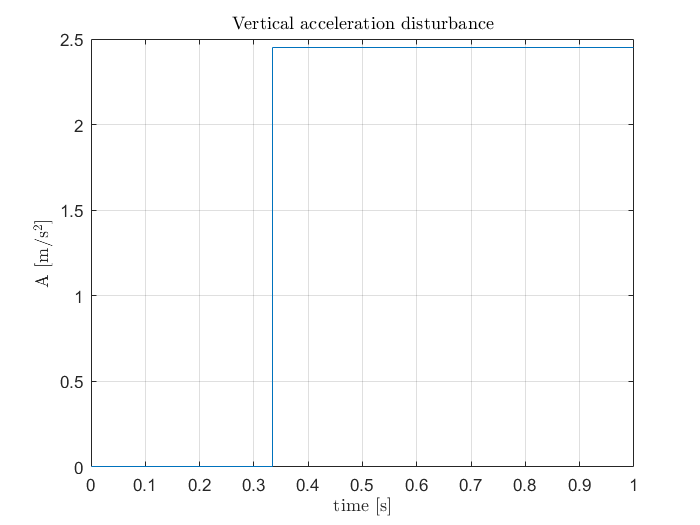


figure
stairs(sima.time,sima.signals.values(:,1))
grid('on')
title('Vertical acceleration disturbance','interpreter','latex')
ylabel('A [m/s$^2$]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

## Observer design for estimation of the external acceleration

In order to determine the unknown acceleration $A$ acting on the measuring device a state estimator in the form of a Kalman filter can be employed.

The position measurement is affected by white noise $w$ with zero mean and noise intensity $V_w = 1\times10^{-10}$, i.e.


$$y = X + w$$


**Problem 5 (6 points)** Under the assumption that the exteral vertical acceleration is constant, **design a discrete time Kalman filter** able to reconstruct the state vector $x = [X,V]^\mathrm{T}$ and the unknown constant acceleration $A$. 

% Your solution goes here

% The Kalman filter should reconstruct the states X,V, and the disturbance
% A
% This requires an augmentation of the system knowing that A is constant
A_kf = [A Bv; zeros(1,3)];
B_kf = [B;0];
[F_kf,G_kf] = c2d(A_kf,B_kf,Ts);
C_kf = [C 0];

% A can be considered a noise for its reconstruction, that enters the 
% process as state 3. Therefore:
Bv_kf = [0;0;1];
Gv_kf = eye(3);

V1 = 100; % Arbitrarily selected noise power for the reconstruction of A
V1d = Bv_kf*V1*Bv_kf'*Ts;

V2 = 1e-10;
V2d = V2/Ts;

% Check the observability of the augmented system
rank(obsv(F_kf,C_kf))-length(F_kf); % Gives 0, therefore, the system is observable

% Obtain the Kalman gain and the filter's calculated properties
[L_kf,P_kf,Q_kf,l_kf_dt] = dlqe(F_kf,Gv_kf,C_kf,V1d,V2d);

**Problem 6 (4 points) **Implement the discrete time Kalman filter in the Simulink diagram of the closed-loop system, and assess the estimation performance of the Kalman filter when tested on the nonlinear system together with the control system designed in Problem 3, both in stationary conditions and in the presence of the step change in the external vertical acceleration $A$ of $0.25g$.

% Your solution goes here

% The Kalman filter is to be implemented with the controller, therefore, it
% is required to check that the Kalman filter operates faster than the
% closed-loop controlled system.
l_kf_ct = log(l_kf_dt)/Ts

l_kf_ct = 	1.0e+02 *

  -0.5198 + 0.8318i
  -0.5198 - 0.8318i
  -1.0395 + 0.0000i


min(abs(l_kf_ct))>max(abs(l_ct))

ans = logical
   1


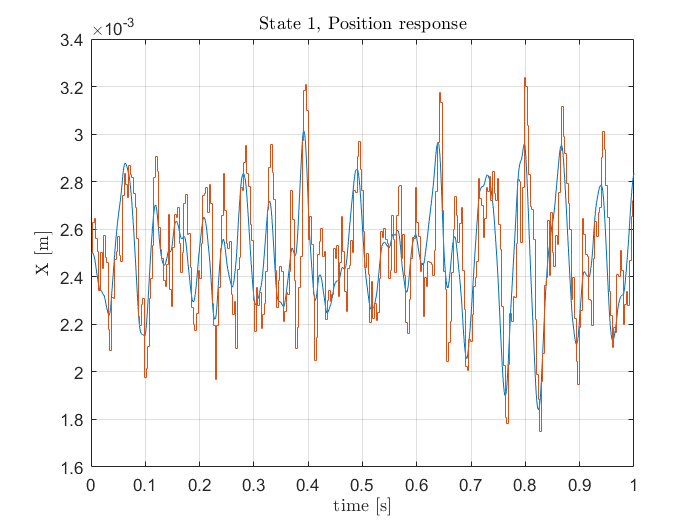

% Find that the fastest controlled-closed loop dynamics are slower than the
% slowest error dynamics. The observer is valid for this system.

% Implement the Kalman filter using appropriate deviation variables.

% Assess the estimation performance on the stationary system.
sim('LQR_KF_stationary')

figure
plot(simx.time,simx.signals.values(:,1))
hold on
stairs(simxh.time,simxh.signals.values(:,1))
hold off
grid('on')
title('State 1, Position response','interpreter','latex')
ylabel('X [m]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

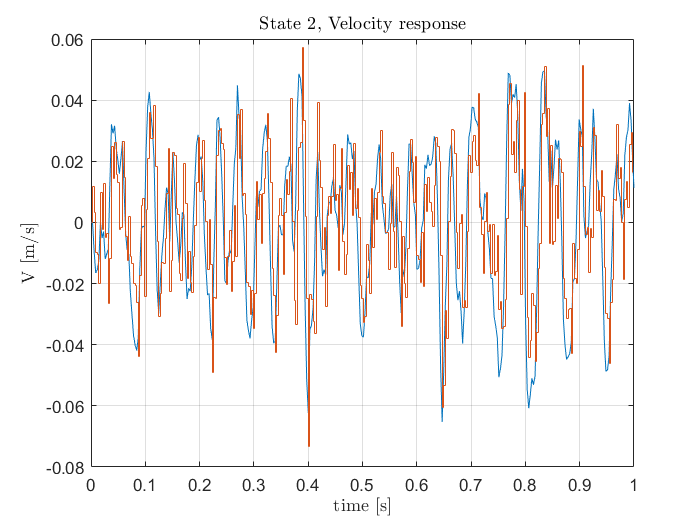


figure
plot(simx.time,simx.signals.values(:,2))
hold on
stairs(simxh.time,simxh.signals.values(:,2))
hold off
grid('on')
title('State 2, Velocity response','interpreter','latex')
ylabel('V [m/s]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

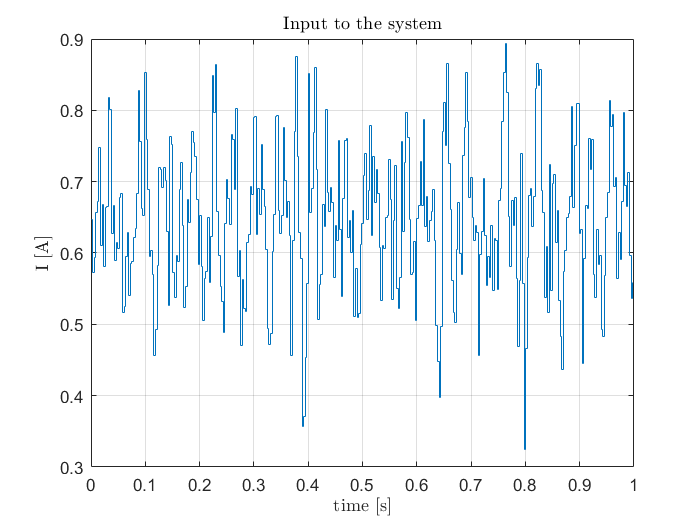


% The estimated states, follow the real states quite well

figure
stairs(simu.time,simu.signals.values(:,1))
grid('on')
title('Input to the system','interpreter','latex')
ylabel('I [A]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

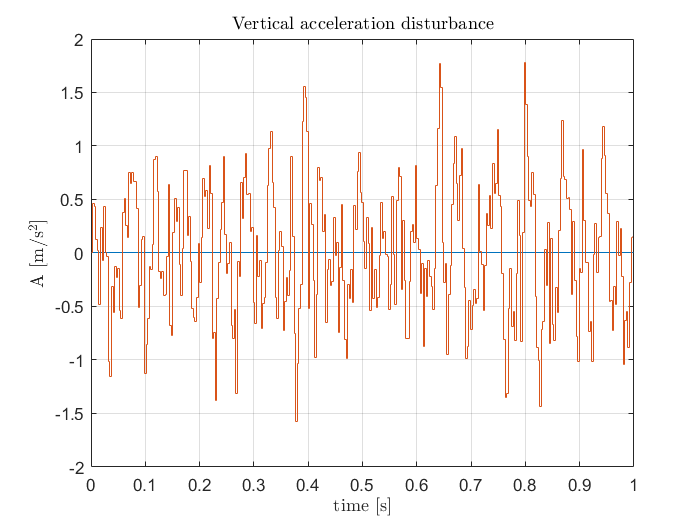


figure
stairs(sima.time,sima.signals.values(:,1))
hold on
stairs(simxh.time,simxh.signals.values(:,3))
hold off
grid('on')
title('Vertical acceleration disturbance','interpreter','latex')
ylabel('A [m/s$^2$]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

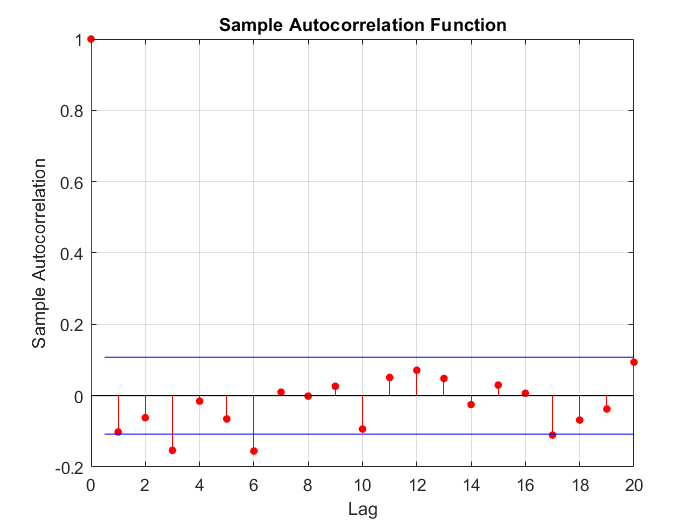


% The estimated disturbance keeps the real disturbance as its mean, as the
% real disturbance tends to be within the center of the amplitude

figure
autocorr(inno.signals.values)
grid('on')


% Autocorrelation of the innovation indicates a good estimation of the
% Kalman filter

% Verify the calculated Q to the simulated response
x_h = simxh.signals.values;
x_sim = xsim.signals.values;
err = x_sim-x_h;
Q_sim = cov(err)

Q_sim =     0.0000    0.0000    0.0001
    0.0000    0.0002    0.0081
    0.0001    0.0081    0.3619


Q_kf

Q_kf =     0.0000    0.0000    0.0001
    0.0000    0.0003    0.0180
    0.0001    0.0180    2.0572


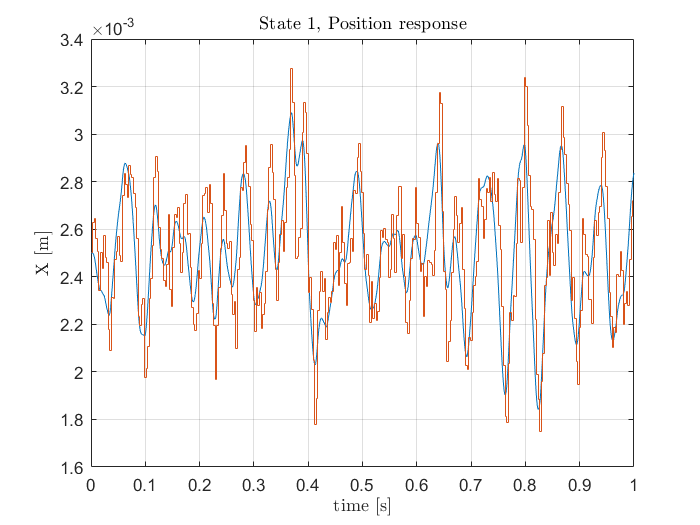

% There is a deviation in terms of the lower right 2x2.

% Assess the estimation performance on the stepped system.
sim('LQR_KF_step')

figure
plot(simx.time,simx.signals.values(:,1))
hold on
stairs(simxh.time,simxh.signals.values(:,1))
hold off
grid('on')
title('State 1, Position response','interpreter','latex')
ylabel('X [m]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

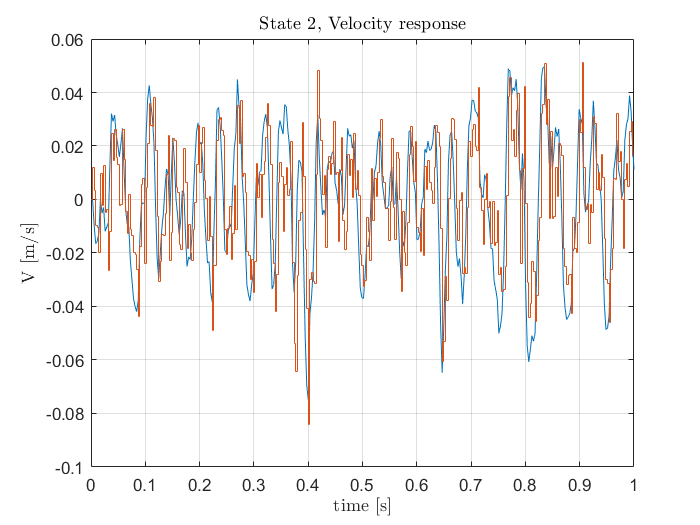


figure
plot(simx.time,simx.signals.values(:,2))
hold on
stairs(simxh.time,simxh.signals.values(:,2))
hold off
grid('on')
title('State 2, Velocity response','interpreter','latex')
ylabel('V [m/s]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

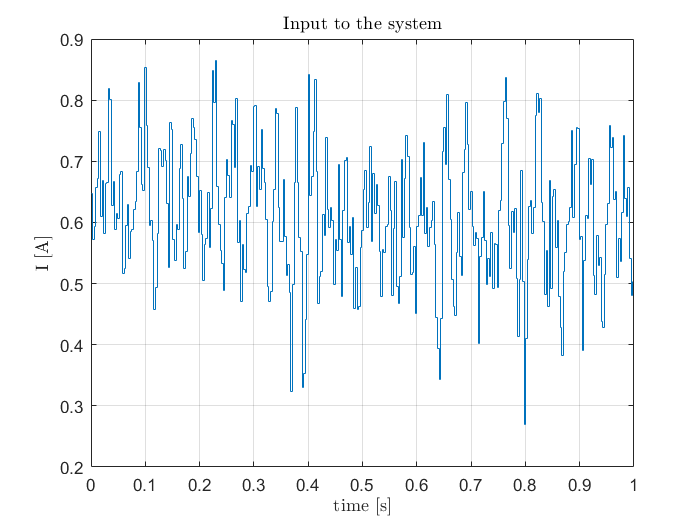


% The estimated states, follow the real states quite well

figure
stairs(simu.time,simu.signals.values(:,1))
grid('on')
title('Input to the system','interpreter','latex')
ylabel('I [A]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

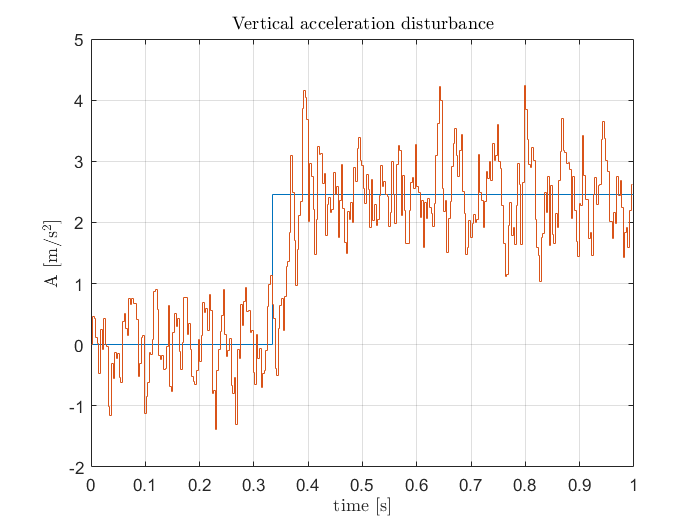


figure
stairs(sima.time,sima.signals.values(:,1))
hold on
stairs(simxh.time,simxh.signals.values(:,3))
hold off
grid('on')
title('Vertical acceleration disturbance','interpreter','latex')
ylabel('A [m/s$^2$]','interpreter','latex')
xlabel('time [s]','interpreter','latex')

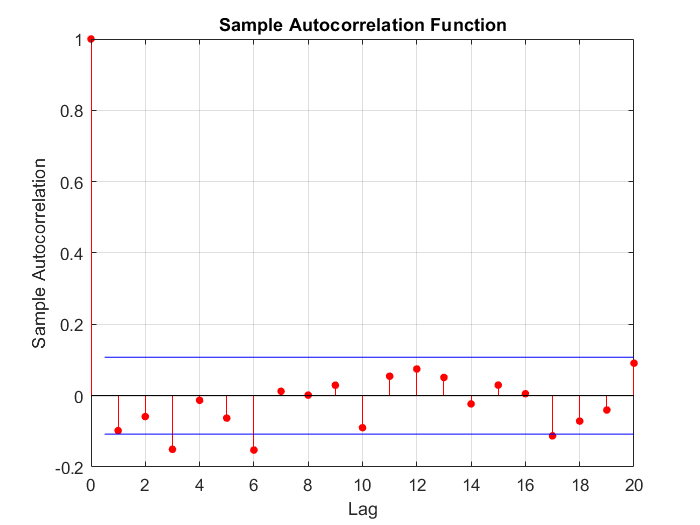


% The estimated disturbance keeps the real disturbance as its mean, as the
% real disturbance tends to be within the center of the amplitude

figure
autocorr(inno.signals.values)
grid('on')


% Autocorrelation of the innovation indicates a good estimation of the
% Kalman filter

% Verify the calculated Q to the simulated response
x_h = simxh.signals.values;
x_sim = xsim.signals.values;
err = x_sim-x_h;
Q_sim = cov(err)

Q_sim =     0.0000    0.0000    0.0001
    0.0000    0.0002    0.0090
    0.0001    0.0090    0.4842


Q_kf

Q_kf =     0.0000    0.0000    0.0001
    0.0000    0.0003    0.0180
    0.0001    0.0180    2.0572


% There is a deviation in terms of the lower right 2x2.

% Most likely, the deviations between Q_sim and Q_kf indicate that there
% was an error in the calculation or use of the random number generator.

% Ultimately, however, the Kalman filter was constructed adequately in
% order to estimate the system states and the disturbance A, using the
% output of the system and the calculated input. It was able to control the
% system as required with the calculated LQR from the previous question.
% This could be seen, as the state X was kept constant despite the
% disturbance in the output, as well as, the step in A.

% This means that the separation principle was true, as the Kalman filter
% and the LQR controller were constructed independently from each other.
